# Hybrid Data Analysis Project

### Name: Harman Kaur Bhambra

### Mtkr no: 12552803

Our objective is to check whether acoustic measurements can be used to identify tool wear. As mentioned in the project description, we have used the healthy tool data(Parts 1 and 2), trained the RRAE model on it and tested it on the worn tool conditions at the later parts(3 to 7).

## Preparing Workspace

clear all;
clc;

## Loading and preparing the dataset

The dataset contains acoustic measurements(y) recorded during CNC milling. Each lane contains 180 samples which represent one revolution of the tool. As mentioned above, the dataset contains measurements from seven parts milled using the same cutting tool. We were previously informed and showed that the first two parts were healthy.

load("C:\Users\DELL\Downloads\Hybrid Data Analysis\Hybrid Data Analysis\Data\Tool3DataOrdered.mat")

1.Convert the data into a matrix

n=length(Tool3DataOrdered); %To find the total number of lane measurements

%The RRAE example as we saw works with matrix data. Therefore, we converted the data into a matrix. 
% Here we made an empty matrix.
ytool=zeros(180,n);

%storing the data from the dataset into the matrix
for i=1 : n
    ytool(:, i)= Tool3DataOrdered(i).y;
end

size(ytool)

ans =    180   224


## Healthy Data Selection

We separate the healthy data from the total data of the dataset. An attribute in the dataset known as 'parts' was used as a condition here. Since the parts 1 and 2 were healthy, the condition has been put accordingly.

partLabels=[Tool3DataOrdered.Part];%we extract the part number corresponding to each lane measurement
healthyLabels= find(partLabels<=2); %It is mentioned that the labels for part 1 and 2 were healthy. Hence, we are identifying those labels here.
yhealthy=ytool(:, healthyLabels);
size(yhealthy)

ans =    180    64


% Prepare the data for training by normalizing the healthy signals
%We will be using these to train the RRAE

## Visualization of the Data before using it for training/testing

Here, we visualize a healthy signal and a worn out signal. To make the comparision we take the first set and the last set of data from the dataset.

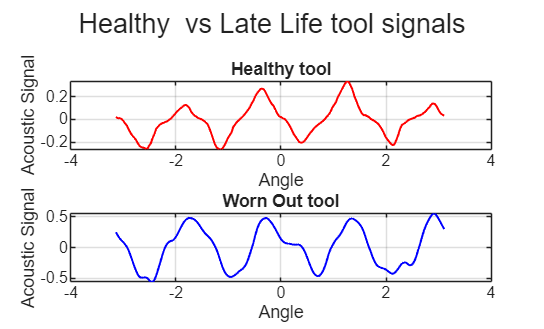

figure;
%divide the graphs into two subplots for better understanding.
subplot(2,1,1)
%good Lane
plot(Tool3DataOrdered(1).x, Tool3DataOrdered(1).y, 'r-','LineWidth',1)
xlabel("Angle")
ylabel("Acoustic Signal")
title("Healthy tool")
grid on;
subplot(2,1,2)
%Bad Lane
plot(Tool3DataOrdered(end).x, Tool3DataOrdered(end).y, 'b-', 'LineWidth',1)
grid on;
title("Worn Out tool")
sgtitle("Healthy  vs Late Life tool signals");
xlabel("Angle")
ylabel("Acoustic Signal")

## Basis Function Selection

The milling process is periodic in nature. Therefore Fourier basis functions were selected as the basis function for the decoder. The objective was to choose a basis function that can represent the dominant characteristics of the data efficiently.

Fourier basis functions are a natural choice since they are widely used to represent periodic phenomena through combination of sine and cosine function. 

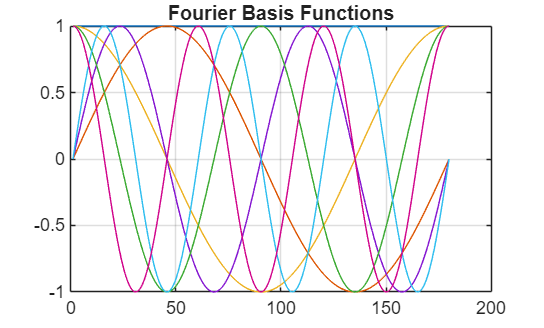

%Constructing Fourier basis functions
theta = linspace(0,2*pi,180)';
%We construct the constant term and the first three elements.
Btool = [ones(180,1), sin(theta), cos(theta),sin(2*theta), cos(2*theta),sin(3*theta), cos(3*theta)];

%plot the function
figure;
plot(Btool)
grid on;
title('Fourier Basis Functions')

## Data Preprocessing for RRAE

[dataCell,dataTest] = generateAEBinputTool3(ytool,partLabels);

## Training on the Healthy Data

As mentioned above, the RRAE was trained ONLY on healthy tool data. The encoder learns a compact latent representation while the decoder is constrained by the selected basis function.

rraeTool = AutoencoderBasisFunCantilever();
rraeTool.trainAEBTool3(ytool,partLabels,Btool);

rraeTool.Trained

ans = logical
   1


save('tool3_rrae_workspace.mat')

## Signal Reconstruction

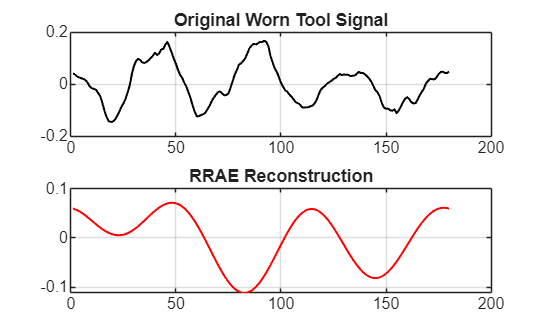

[reconstruct_out, latent_rep, dataTest] =rraeTool.predictAEBTool3(ytool,partLabels);
figure;
subplot(2,1,1)
%Original worn tool signal
plot(dataTest{1},'k-','LineWidth',1)
grid on;
title('Original Worn Tool Signal')
subplot(2,1,2)
%RRAE reconstruction
plot(reconstruct_out{1},'r-','LineWidth',1)
grid on;
title('RRAE Reconstruction')

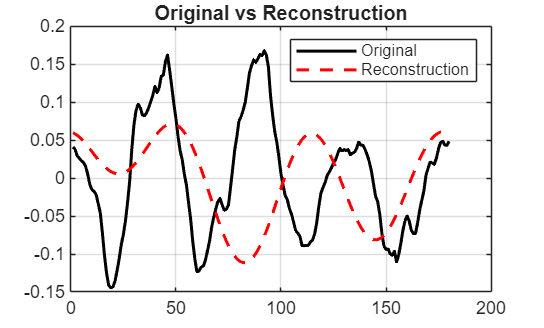

%Comparison graph between the two
figure;
plot(dataTest{1},'k-','LineWidth',1.5)
hold on;
plot(reconstruct_out{1},'r--','LineWidth',1.5)
legend('Original','Reconstruction')
grid on;
title('Original vs Reconstruction')

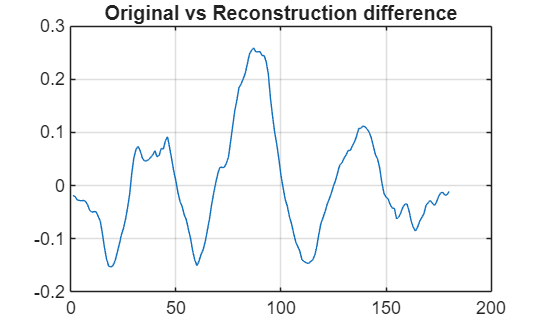

figure;
plot(dataTest{1}-reconstruct_out{1})
title('Original vs Reconstruction difference');
grid on;

## Error Calculation

The error quantifies the deviation between the measured signal and the reconstruction.

err=zeros(length(dataTest),1);
for i=1:length(dataTest)
    err(i)=mean((double(dataTest{i})-double(reconstruct_out{i})).^2);
end
mean(err)

ans = 0.0647

max(err)

ans = 0.1690

min(err)

ans = 0.0056

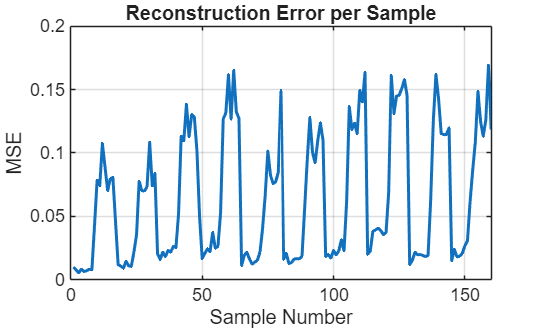

%Plot the MSE on the graph
figure;
plot(err,'LineWidth',1.5)
grid on;
xlabel('Sample Number')
ylabel('MSE')
title('Reconstruction Error per Sample')

## Analysis of the Error

Here, we create a box plot to analyse the error.

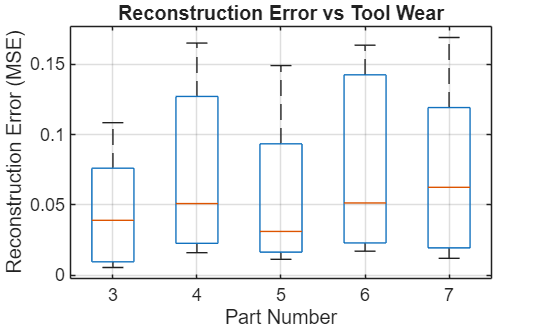

%Keep the labels only corresponding to the test data.
%We remove the healthy training samples here
testPartLabels = partLabels(partLabels > 2);
%Compare reconstruction error distributions for different wear stages.
%Higher error indicates signals that differ more from the healthy behaviour learned by the RRAE
figure;
boxplot(err,testPartLabels)
%Last wear stages show higher reconstruction errors and larger variability.
xlabel('Part Number')
ylabel('Reconstruction Error (MSE)')
title('Reconstruction Error vs Tool Wear')
grid on;

Mean Error

for j = 3:7
    fprintf('Part %d mean error = %.4f\n',j, mean(err(testPartLabels==j)));
end

Part 3 mean error = 0.0442
Part 4 mean error = 0.0721
Part 5 mean error = 0.0549
Part 6 mean error = 0.0801
Part 7 mean error = 0.0723


## Conclusion

The objective of the project was to investigate whether a RRAE could be used to identify tool wear from acoustic measurements recorded during a milling process. To achieve this, we used the Tool3 dataset. It was analysed and healty parts(1 and 2) were used for training purposes.

A Fourier basis function consisting of a constant term and first three harmonic components were selected as the basis function for the decoder. We took this choice because of the periodic nature of the milling process where the cutter rotates and engages with the workpiece repeatedly. The basis function provided a compact representation of the dominant signal behaviour while it maintained a low-dimensional latent space.

After training, we applied RRAE to measurements from Parts 3 to 7. The reconstructed signals captured the overall shape of the original measurements but smoothed many of the higher frequency variations. The errors were calculated and analysed for each wear stage.

The results showed that the reconstruction error varied across the different tool conditions, with worn tool measurements generally producing larger errors than the healthy data used during training. This means that the RRAE could learn the characteristics of normal operation and identify deviations from this behaviour.

Therfore, the project could overall demonstrate that reconstruction-based approaches can be used a tool condition monitoring technique. The error provides a meaningful indicator of changes in the acoustic signal and therefore has potential for detecting tool wear and abnormal operating conditions.